Load transfer ratio: steer; mu = 0.85

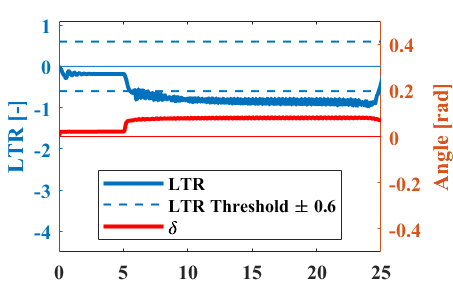



load('..\CarSim outputs\FP FN\LastRunLastRunLTR_FPFN.mat')

ltr_e = LTR(Ay*9.81, 9.81, 0.9345, 1.675); % 0.728m -> 250kg  0.9345m -> 600kg

f = figure;
f.Units = 'centimeters';
f.Position = [10 10 8 5];

hold on;
yyaxis left
l1 = plot(Time, ltr_e,'LineWidth', 2, 'DisplayName','LTR');
ylabel('LTR [-]')

% Abnormal message
yyaxis right
delta = deg2rad((Steer_R1 + Steer_L1)/2); 
l2 = plot(Time,delta, 'r','LineWidth', 2, 'DisplayName','\delta');
ylabel('Angle [rad]')


% % Defence
% yyaxis left
% load('E:\HK\RA\Vehicle dynamics\Matlab\SystemIdentification\CarSim outputs\With Cargo\LTR only\LastRunLTR100kph0degDef.mat')
% 
% ltr_e = LTR(Ay*9.81, 9.81, 0.9345, 1.675); % 0.728m -> 250kg  0.9345m -> 600kg
% 
% l3 = plot(Time, ltr_e, '-.','LineWidth', 2, 'DisplayName','LTR (defense)');

%% Threshold
yyaxis left
l4 = plot(Time, ones(length(Time),1)*0.6, '--','LineWidth', 1, 'DisplayName','LTR Threshold \pm 0.6');
l5 =  plot(Time, -ones(length(Time),1)*0.6, '--','LineWidth', 1);

ylim([-4.5 1.1])

% % Abnormal message
yyaxis right
% delta = deg2rad((Steer_R1 + Steer_L1)/2); 
% % l6 = plot(Time,delta, '-.','LineWidth', 2, 'DisplayName','\delta (defense)');
% ylabel('Angle [rad]')

ylim([-0.5 0.5])
yticks(-0.4:0.2:0.4)

Xlim = [0 25];
xlim(Xlim)
yyaxis left
l0l = plot(Xlim,[0 0], '-','LineWidth', 0.5);
yyaxis right
l0r = plot(Xlim,[0 0], 'r-','LineWidth', 0.5);
    
legend([l1 l4 l2 ],'location','south');


set(gca, 'FontName','Times New Roman','FontSize',10, 'FontWeight', 'bold');

box on

% exportgraphics(gcf,'LTRsteerFPFN.pdf','ContentType','vector')

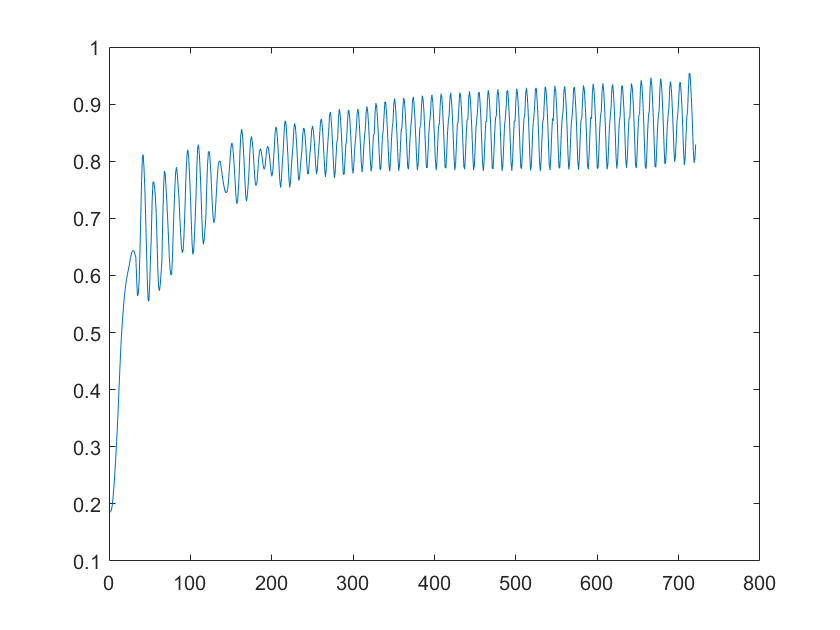

figure

ltr_total_attack = -ltr_e(and((Time > 5 ), (Time < 23)));
plot(ltr_total_attack)

n_ltr_total_attack = length(ltr_total_attack);


fn04 = 100 - length(ltr_total_attack(ltr_total_attack>0.4)) / n_ltr_total_attack * 100

fn04 = 1.6644

fn05 = 100 - length(ltr_total_attack(ltr_total_attack>0.5)) / n_ltr_total_attack * 100

fn05 = 2.0804

fn06 = 100 - length(ltr_total_attack(ltr_total_attack>0.6)) / n_ltr_total_attack * 100

fn06 = 4.5770

fn07 = 100 - length(ltr_total_attack(ltr_total_attack>0.7)) / n_ltr_total_attack * 100

fn07 = 10.4022

fn08 = 100 - length(ltr_total_attack(ltr_total_attack>0.8)) / n_ltr_total_attack * 100

fn08 = 36.3384

fn09 = 100 - length(ltr_total_attack(ltr_total_attack>0.9)) / n_ltr_total_attack * 100

fn09 = 85.4369


FN_ltr = [fn04 fn05 fn06 fn07 fn08 fn09 ]';
